# State Space Modelling of 2DOF Linear Vehicle Model

Bicycle model of the vehicle is shown in the figure below;

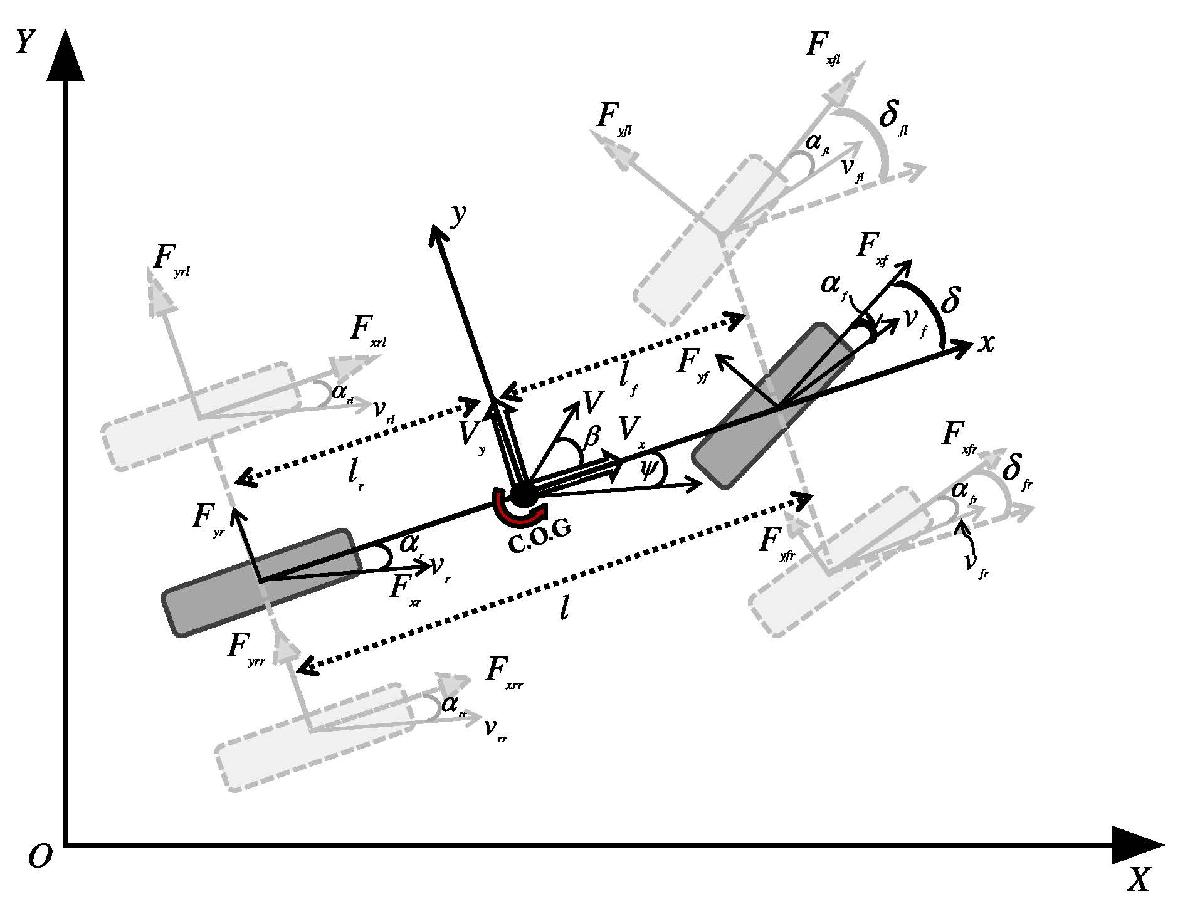

For yaw stability control application using steering control; only two states have been taken under consideration viz. $\left\lbrack \begin{array}{c}
\psi^˙ \\
\beta 
\end{array}\right\rbrack$. The control taskis to restore the yaw rate to nominal motion.

We consider $C_f =C_{1f} +C_{2f} \;$and $\;C_r =C_{1r} +C_{2r}$. Wherein, $C_{i\;f} =\frac{F_{\textrm{yfi}} }{\alpha_{\textrm{fi}} }$ and $C_{i\;r} =\frac{F_{\mathrm{y}r\mathrm{i}} }{\alpha_{\textrm{ri}} }$ .

The state space equations are given as:

## 
$$\left\lbrack \begin{array}{c}
\beta^˙ \\
\psi^¨ 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{C_f +C_r }{{\textrm{mV}}_x } & -1-\frac{l_f C_f -l_r C_r }{{\textrm{mV}}_x^2 }\\
-\frac{l_f C_f -l_r C_r }{I_z } & -\frac{l_f^2 C_f +l_r^2 C_r }{I_z V_x }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta \\
\psi^˙ 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\frac{C_f }{{\textrm{mV}}_x }\\
\frac{l_f C_f }{I_z }
\end{array}\right\rbrack \delta_f$$


## Initialization

clc;clear;
load('Params_2Cf_2Cr_15mps.mat')
T_final=time(end)

T_final = 8.2000

T_sample=T

T_sample = 0.1000

## Code for System Modelling

A=[-(Cf+Cr)/(m*Vx), -1-(lf*Cf-lr*Cr)/(m*Vx^2);
    -(lf*Cf-lr*Cr)/Iz, -(lf^2*Cf+lr^2*Cr)/(Iz*Vx)]

A =    -4.4021   -0.8307
   20.8696   -5.1868



B=[Cf/(m*Vx);(lf*Cf)/Iz]

B =     1.6085
   15.8609



C=eye(2)

C =      1     0
     0     1



D=[0]

D = 0


sys=ss(A,B,C,D)


sys =
 
  A = 
            x1       x2
   x1   -4.402  -0.8307
   x2    20.87   -5.187
 
  B = 
          u1
   x1  1.608
   x2  15.86
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



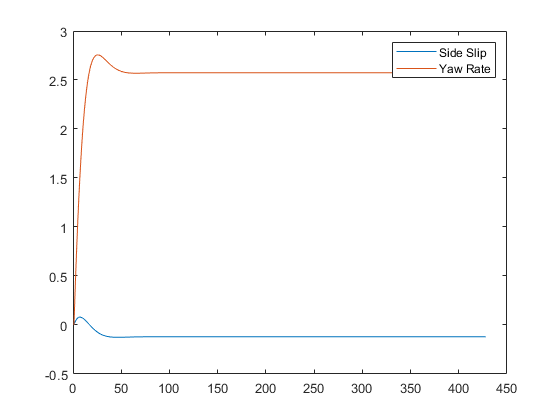


plot(step(sys,T_final))
legend('Side Slip','Yaw Rate')

## Discretization of Continous State Space Model

sysd=c2d(ss(A,B,C,D),T_sample);

Ad=sysd.A

Ad =     0.5903   -0.0500
    1.2554    0.5431


Bd=sysd.B

Bd =     0.0793
    1.3271


Cd=sysd.C

Cd =      1     0
     0     1


Dd=sysd.D

Dd =      0
     0


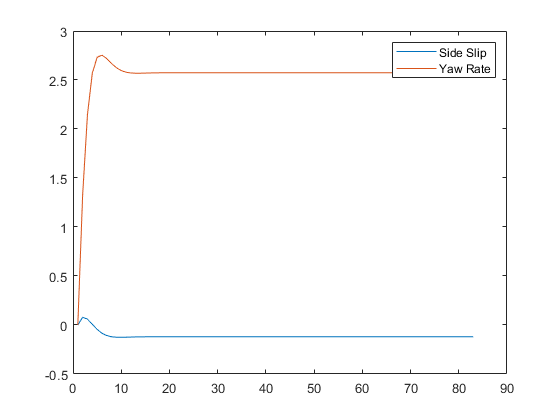


plot(step(sysd,T_final))
legend('Side Slip','Yaw Rate')

## Testing controllability of the system

For Continous Time System Model:

Continous_Controllability=ctrb(A,B)

Continous_Controllability =     1.6085  -20.2561
   15.8609  -48.6989



Rc=rank(Continous_Controllability)

Rc = 2


Cont_Unctrb_States=length(A)-Rc;

if Cont_Unctrb_States==0
    disp('The system is Controllable')
else
    disp('The system is Uncontrollable\n')
    disp('No. of Uncontrollable States = ',Cont_Unctrb_States)
end

The system is Controllable


For Discrete Time System Model:

Discrete_Controllability=ctrb(A,B)

Discrete_Controllability =     1.6085  -20.2561
   15.8609  -48.6989



Rd=rank(Discrete_Controllability)

Rd = 2


Dis_Unctrb_States=length(A)-Rc;

if Dis_Unctrb_States==0
    disp('The system is Controllable')
else
    disp('The system is Uncontrollable')
    disp('No. of Uncontrollable States = ',Dis_Unctrb_States)
end

The system is Controllable


## Linear Quadratic Integral Controller Design

The basic structure of an LQI control loop has been given below.

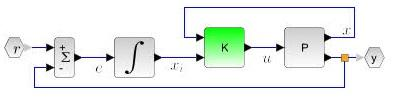

## *Type-1:*

In this section, the 'lqi' command is used for controller designing. The control task is to regulate $\beta \;$ and track $\psi^˙$.

**Step 1.1**: Modulating the C matrix for Tracking

C_lqi=[1 0; 0 1]

C_lqi =      1     0
     0     1


*This step is avoided due to the following error regarding matrix dimension*

**Step 1.2**: Choosing weights for Q and R matrices

**Working Q=diag[10,10,100,1000] and R=100

w_slip=10;
w_yawRate=1;
w_steer=10;
w_errYawRate=1000;
w_errSlip=100;

Q_lqi=diag([w_slip,w_yawRate,w_errSlip,w_errYawRate])

Q_lqi =           10           0           0           0
           0           1           0           0
           0           0         100           0
           0           0           0        1000



R_lqi=[w_steer]

R_lqi = 10

**Step 1.3.a**: LQI formulation for Continous Time State space Model.

Kc_lqi_t1=lqi(ss(A,B,C_lqi,D),Q_lqi,R_lqi)

Kc_lqi_t1 =     1.0174    0.8364    0.0467   -9.9989


**Step 1.3.b**: LQI formulation for Discrete Time State Space Model

Kd_lqi_t1=lqi(ss(Ad,Bd,C_lqi,D),Q_lqi,R_lqi)

Kd_lqi_t1 =  -472.3292   33.3909    0.1598    9.9872


## *Type-2*

Here, the  augmented model has been designed manually and the lqi is realized using LQR command. The augmented model is given as;

$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{x_i } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & 0\\
-C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
x_i 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\\
D
\end{array}\right\rbrack u+\left\lbrack \begin{array}{c}
0\\
-1
\end{array}\right\rbrack r$ where ' ***r ****'* is the reference.

**Step 2.1**: Modulating the C matrix for tracking1

*** (Same as Step 1.1)***

**Step 2.2:** Designing Augmented System Model

Ac_aug = [A zeros(length(A),length(C)); -C zeros(length(C_lqi))]

Ac_aug =    -4.4021   -0.8307         0         0
   20.8696   -5.1868         0         0
   -1.0000         0         0         0
         0   -1.0000         0         0


Bc_aug =[B;zeros(length(C_lqi),1)]

Bc_aug =     1.6085
   15.8609
         0
         0


**Step:2.3:** Choosing weights for Q and R matrices

 ***(Same as Step 1.2)***

**Step 2.4:** Formulation LQR Control using Augmented System (thereby formiing LQI)

Kc_aug_lqi=lqr(Ac_aug,Bc_aug,Q_lqi,R_lqi)

Kc_aug_lqi =     1.0174    0.8364    0.0467   -9.9989


## ***Type-3***

Here, the LQR formulation is done by solving the ARE for the Augmented System

The function `[X,L,G] = care(A,B,Q,R) is used.`

`The said ARE is given as; `$A^T P\;E+P\;A\;E-\left(E^T P\;B+S\right)R^{-1} \left(B^T P\;E+S^T \right)+Q=0$; with $E=1$and $S=0$, it can be reduced to;

$A^T P+P\;A-P\;B\;R^{-1} B^T P+Q=0$. The formulation is given below

***Step 3.1, 3.2 and 3.3 are the same as Step 2.1, 2.2 and 2.3 respectively.***

**Step 3.4:**

P=care(Ac_aug,Bc_aug,Q_lqi,R_lqi)

Error using care (line 123)
The specified Riccati equation does not have a finite solution.

Kc_areSolve=R_lqi\Bc_aug'*P

## **Simulation using Simulink model and Plot of system response with designed controller**

sim('LQR_Lateral_Stability')
subplot(2,1,1)
plot(simTime,slipRef,'r.-',simTime,slipOut,'b-')
subplot(2,1,2)
plot(simTime,yawRef,'r.-',simTime,yawOut,'b-')